%question1
Wp = 10/360; Ws = 20/360;
Rp=1;
Rs=40;
[n,Wn] = buttord(Wp,Ws,1,40)

n = 8

Wn = 0.0313

[b,a] = butter(n,Wn)

b = 1.0e-08 *

    0.0027    0.0213    0.0747    0.1494    0.1867    0.1494    0.0747    0.0213    0.0027


a =     1.0000   -7.4961   24.5985  -46.1536   54.1545  -40.6902   19.1190   -5.1361    0.6040


H=tf(b,a,1/720)

H =
 
                                                                                               
  2.668e-11 z^8 + 2.134e-10 z^7 + 7.47e-10 z^6 + 1.494e-09 z^5 + 1.867e-09 z^4 + 1.494e-09 z^3 
                                                                                               
                                                       + 7.47e-10 z^2 + 2.134e-10 z + 2.668e-11
                                                                                               
  ---------------------------------------------------------------------------------------------
                                                                                              
  z^8 - 7.496 z^7 + 24.6 z^6 - 46.15 z^5 + 54.15 z^4 - 40.69 z^3 + 19.12 z^2 - 5.136 z + 0.604
                                                                                              
 
Sample time: 0.0013889 seconds
Discrete-time transfer function.



[z,p,k]=butter(n,Wn)

z =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


p =    0.9078 + 0.0175i
   0.9078 - 0.0175i
   0.9201 + 0.0504i
   0.9201 - 0.0504i
   0.9437 + 0.0774i
   0.9437 - 0.0774i
   0.9765 + 0.0945i
   0.9765 - 0.0945i


k = 2.6677e-11

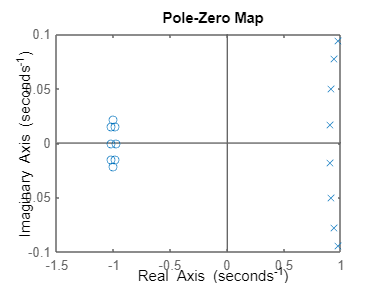

pzplot(tf(b,a));

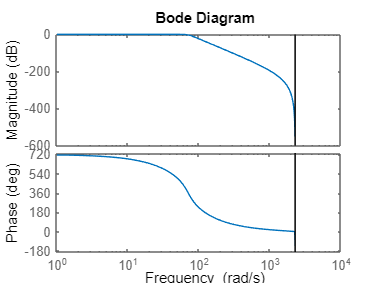

figure;
bode(H)

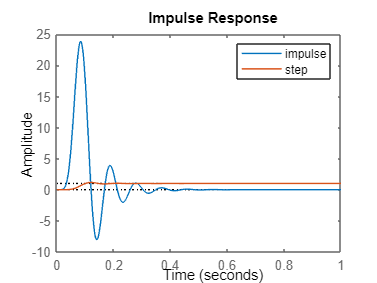

figure;
impulse(H,1)
hold on
step(H,1)
legend('impulse', 'step')

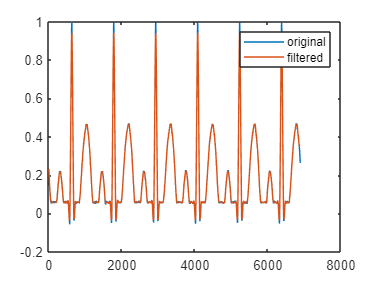

%question 2
Wp = 10/360; Ws = 20/360;
[n,Wn] = buttord(Wp,Ws,1,40);
[b,a] = butter(n,Wn);
data=load('ECG_Data.txt');
figure;
plot(data)
hold on 
plot(filtfilt(b, a, data))
legend('original','filtered')

%question 4
[ n2 , Wp ] = cheb1ord( Wp , Ws , Rp , Rs ) 

n2 = 5

Wp = 0.0278

[b2,a2] = cheby1(n2,Rp,Wp)

b2 = 1.0e-06 *

    0.0187    0.0933    0.1866    0.1866    0.0933    0.0187


a2 =     1.0000   -4.9088    9.6487   -9.4923    4.6740   -0.9215


H1=tf(b2,a2,1/720)

H1 =
 
  1.866e-08 z^5 + 9.331e-08 z^4 + 1.866e-07 z^3 + 1.866e-07 z^2 + 9.331e-08 z + 1.866e-08
  ---------------------------------------------------------------------------------------
                z^5 - 4.909 z^4 + 9.649 z^3 - 9.492 z^2 + 4.674 z - 0.9215
 
Sample time: 0.0013889 seconds
Discrete-time transfer function.



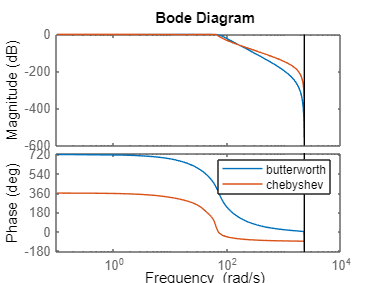

figure;
bode(H)
hold on 
bode(H1)
legend('butterworth','chebyshev')

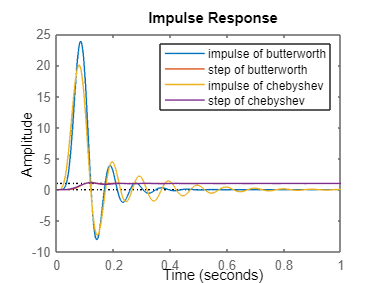

figure;
impulse(H,1)
hold on
step(H,1)
hold on 
impulse(H1,1)
hold on 
step(H1,1)
legend('impulse of butterworth', 'step of butterworth','impulse of chebyshev', 'step of chebyshev')

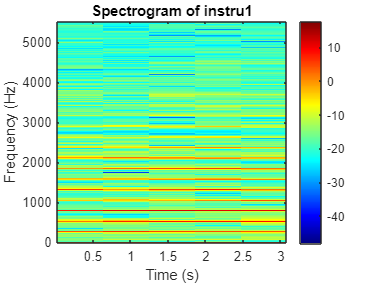

%question3
[y1, Fs] = audioread('instru1.wav');
window_length = 7250;  
overlap = 512;        
nfft = 7250;           
[S, f, t] = spectrogram(y1, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  
colormap('jet');  
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of instru1');
colorbar; 

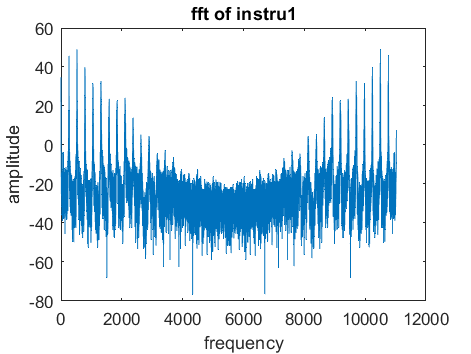

figure;
fft_opera=abs(fft(y1));
freqs = (0:length(fft(y1))-1) * (Fs /length(fft(y1))); Freq=freqs;
plot(Freq,20*log10(fft_opera))
title("fft of instru1")
xlabel("frequency")
ylabel("amplitude")



fundamental_frequency = 262.247;  
Fs = 11025;  
normalized_fundamental_frequency = fundamental_frequency / (Fs / 2);
Rp = 1;  
Rs = 50; 
[n, Wn] = buttord(0.001,normalized_fundamental_frequency,Rp, Rs);
[b3,a3]=butter(n,Wn);
filtered_signal=filtfilt(b3, a3, y1);
H3=tf(b3,a3,1/Fs)

H3 =
 
  1.762e-05 z^2 + 3.524e-05 z + 1.762e-05
  ---------------------------------------
          z^2 - 1.988 z + 0.9882
 
Sample time: 9.0703e-05 seconds
Discrete-time transfer function.



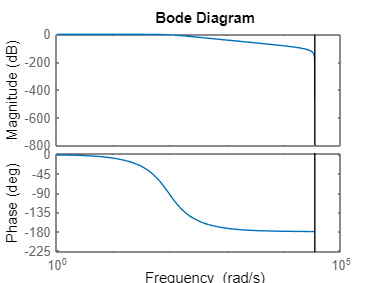

figure;
bode(H3)

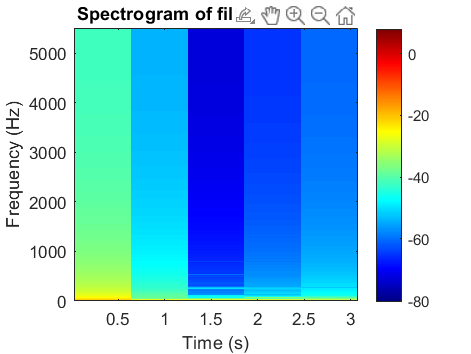

output_filename='filtered_audio.wav';
audiowrite(output_filename, filtered_signal, Fs);
sound(filtered_signal, Fs)
window_length = 7250;  
overlap = 512;        
nfft = 7250;           
[S, f, t] = spectrogram(filtered_signal, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  
colormap('jet');  
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of filt+ered instru1');
colorbar; 

figure;


